# Analysis pipeline for unsupervised classification of song pulses

Data analysis pipeline used to classifiy pulse from set of pulses detected by the song segmenter ([https://github.com/murthylab/songSegmenter](https://github.com/murthylab/songSegmenter)). To make this run fast, the script 1) uses a random subset of 2583 out of 71029 pulses from the *Drosophila melanogaster *strain NM91, 2) loads pre-computed tSNE embeddings (can be re-run by uncommenting some code below).

The code generating this page is hosted at [https://github.com/murthylab/pulseTypePipeline](https://github.com/murthylab/pulseTypePipeline).

addpath('src', 'src.tsne')    % make code available to matlab
load('dat/NM91_pulses.mat')   % load pulse shapes (random subset)

## Normalize pulses

A plot of the raw pulse waveforms reveals that there is considerable variability in the waveforms, most of which stems from the recording situation, not from the male generating highly variable pulses:

- The **amplitude** of the recorded waveforms depends on the distance to the microphone and on the intensity with which the male generates the pulse. We normalize all waveforsm to unit-norm.

- The **sign** of the recorded waveform depends on whether the male is in front or behind the microphone. We adjust pulse sign by ensuring that the pulse is on average positive in the millisecond preceeding the pulse center.

This greatly reduces the pulse variability and reveals a separation of pulse shapes into two clusters.

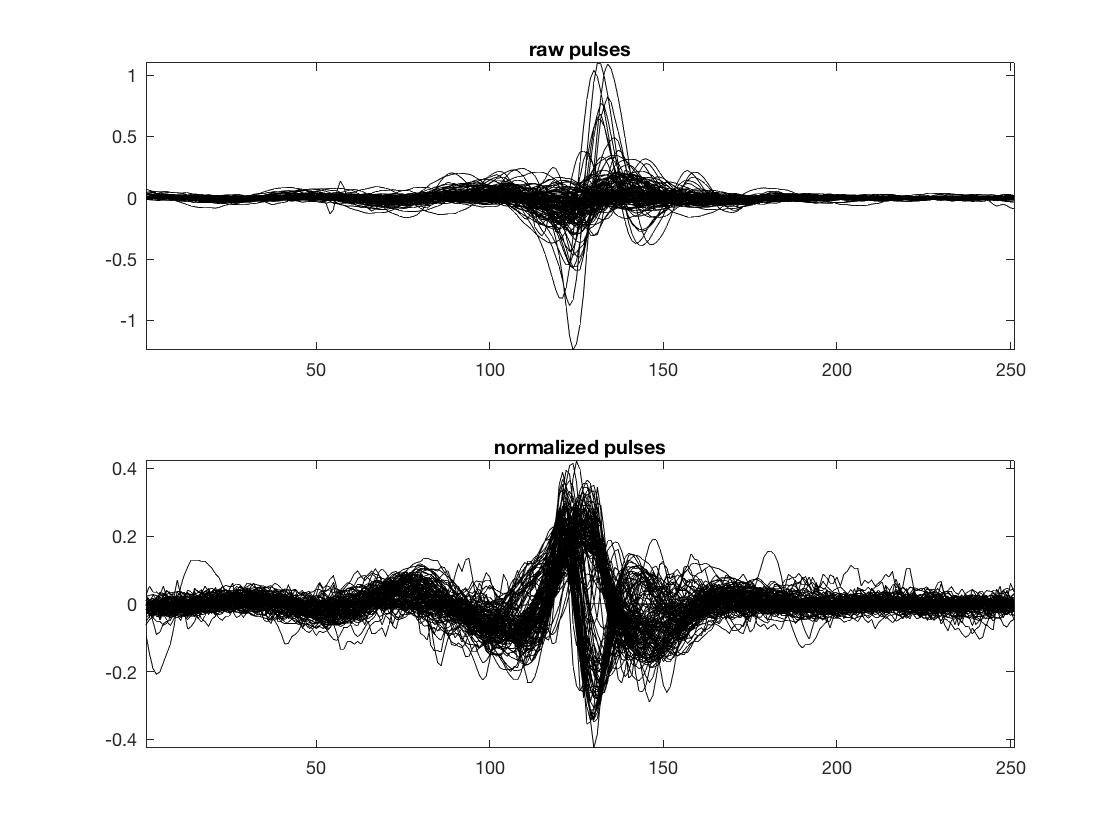

pulseShapesNorm = normalizePulses(pulseShapes);
subplot(211)
plot(pulseShapes(1:20:end,:)','k')
title('raw pulses')
axis('tight')
subplot(212)
plot(pulseShapesNorm(1:20:end,:)','k')
title('normalized pulses')
axis('tight')

## Dimensionality reduction

To facilitate visualization and clusterin of the pulse waveforms, we reduced the dimensioanlity of the pulse waveforms from 251 samples to 2 using alternative methods for dimensionality reduction: principal component analysis (PCA) and t-distributed stochastic neighbor embedding (tSNE, L.v.d. Maaten). Both methods yield similar results but tSNE provides a clearer and more reproducible separation of pulse modes.

The first principal component (PC1) explains ~50% and the distribution of projection values onto PC is bimodally disributed - indicating that pulses fall into two classes.

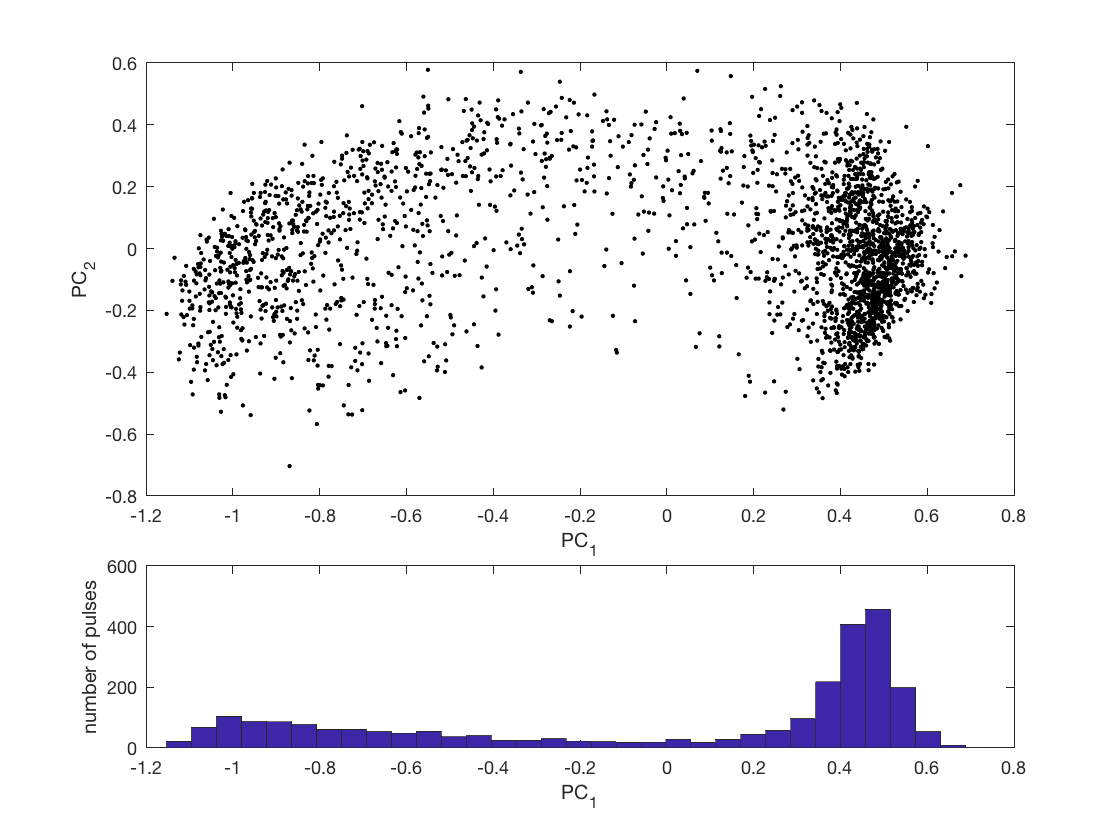

[coeff, score, latent] = pca(pulseShapesNorm);
clf
subplot(3,1,1:2)
plot(score(:,1), score(:,2),'.k')
xlabel('PC_1')
ylabel('PC_2')

subplot(313)
hist(score(:,1), 32)
xlabel('PC_1')
ylabel('number of pulses')

tSNE embedded pulses also fall into two major clusters - confirming the results from PCA.

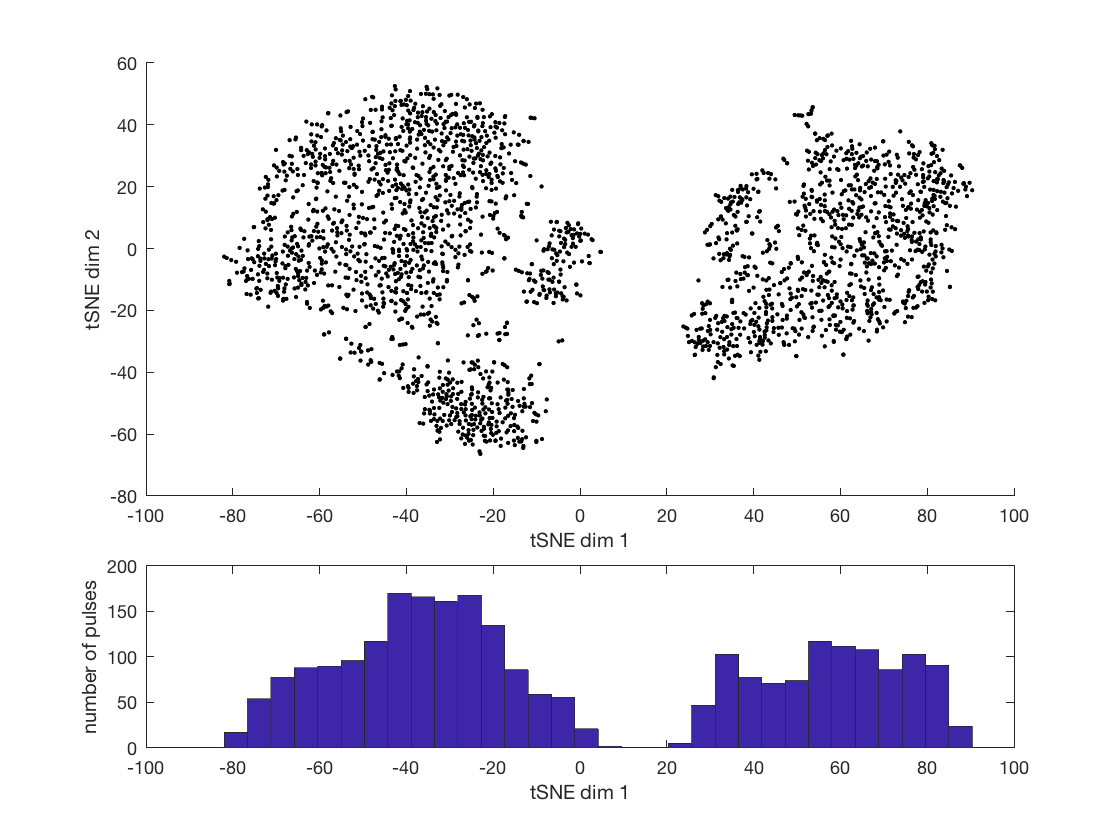

output_dims = 2;
initial_dims = 30;   % tsne default
perplexity = 30;     % tsne default
verbosity = 0;       % silence tsne

% tSNE embedding takes a couple of minutes - we load pre-computed results as a default 
load('res/NM91_tsne')

% uncomment if you want to-run the tSNE embedding yourself
% tsne version found on https://lvdmaaten.github.io/tsne/
% tSNE = tsne(pulseShapesNorm, [], output_dims, initial_dims, perplexity, verbosity);
% matlab's stats toolbox for versions R2017a+ comes with tsne
% tSNE = tsne(pulseShapesNorm, ...
%             'Algorithm', 'barneshut', 'NumDimensions', output_dims,...
%             'NumPCAComponents', initial_dims, 'Perplexity', perplexity);

clf
subplot(3,1,1:2)
scatter(tSNE(:,1), tSNE(:,2), '.k')
xlabel('tSNE dim 1')
ylabel('tSNE dim 2')

subplot(3,1,3)
hist(tSNE(:,1), 32)
xlabel('tSNE dim 1')
ylabel('number of pulses')

## Clustering

To separate pulses into classes, we used two steps of unsupervised clustering methods

- Watershed clustering is used to partition the tSNE distribution into subclusters. This overpartitions pulses, since very similar pulses are split into multiple subclusters

- Subclusters are consolidated using hierarchical clustering on the subcluster centroids. This reveals to pulse types.

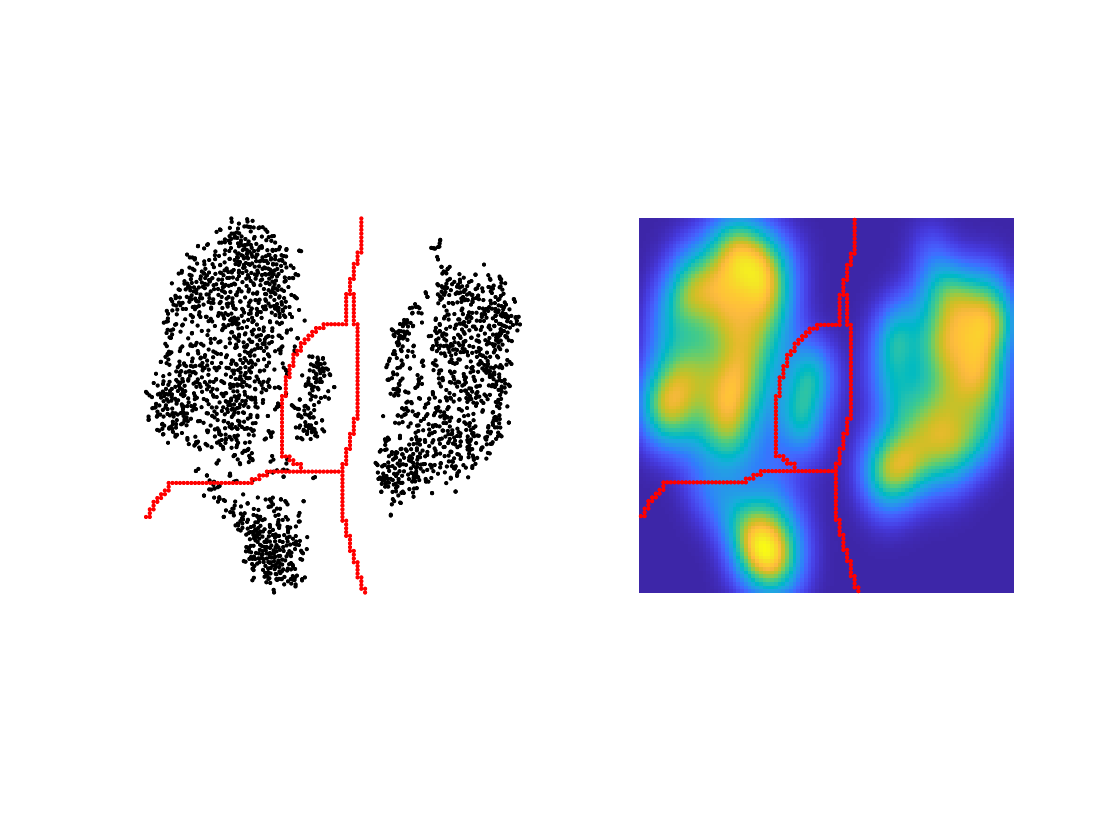

[Gpre, ~, Z0, L, L0, XX] = clusterWaterShed(tSNE, 100);
[boundaryY,boundaryX] = find(L0==0);
subplot(121)
scatter(tSNE(:,1),tSNE(:,2),'.k')
hold on
plot(XX{1}(boundaryX),XX{2}(boundaryY),'.r')
subplot(122)
imagesc(XX{1}, XX{2}, Z0)
hold on
plot(XX{1}(boundaryX),XX{2}(boundaryY),'.r')
colormap(parula(256));
axis(gcas, 'square', 'tight', 'off', 'xy')

## Consolidate clusters

Cluster consolidation yields two pulse types:

- A slow, symmetrical pulse with a Mexican-hat like shape, termed Pslow

- A faster, asymmetrical pulse with a biphasic shape, termed Pfast

centroidsPre = grpstats(pulseShapesNorm, Gpre); % compute centroids for watershed clusters
centroidTSNEpre = grpstats(tSNE, Gpre);
Gc = clusterdata(centroidsPre,2);               % cluster centroids
Gw = mapVal(Gpre, unique(Gpre)', Gc');          % assign consolidated cluster labels to each pulse
centroids = grpstats(pulseShapesNorm, Gw);      % get consolidated centroids
centroidTSNE = grpstats(tSNE, Gw);
Gw = mapVal(Gw, argsort(argmax(centroids')), 1:size(centroids,1)); % sort by "speed" so P2 is always first
cmap = lines(max(Gpre)+2);

clf
subplot(1,6,1:2)
gscatter(tSNE(:,1), tSNE(:,2), Gpre, cmap(3:end,:), '.', [],[],'off')
hold on
for cnt = 1:size(centroidsPre,1)
   plot((1:size(centroidsPre,2)-120)/5 + centroidTSNEpre(cnt,1)-12, ...
        50*centroidsPre(cnt,60:end-60-1)+centroidTSNEpre(cnt,2), 'k','LineWidth', 1.5)
end
hold off
axis(gca, 'square', 'tight', 'off')
title('watershed')

colors = lines(2);
subplot(1,6,3)
Z = linkage(centroidsPre);
colormap(lines(2))
h = dendrogram(Z, 'Orientation','left', 'Reorder',argsort(Gc));

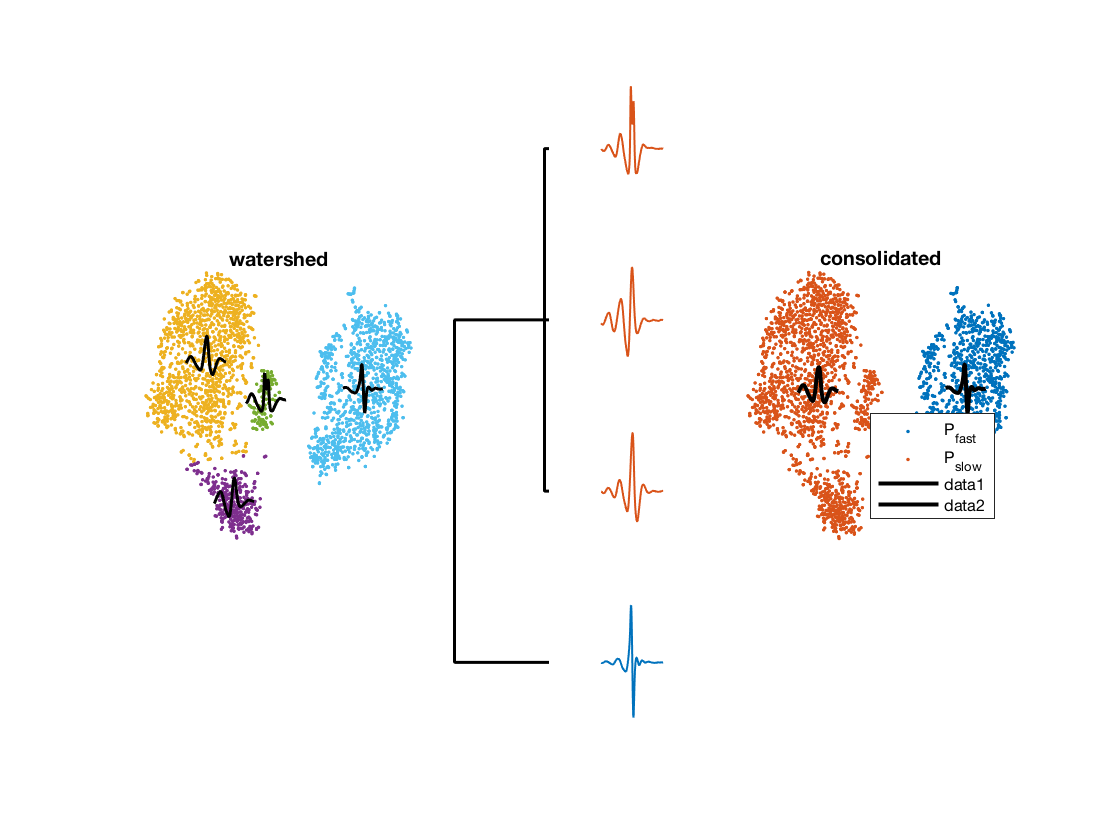

set(h, 'LineWidth',1.5, 'Color', 'k')
axis('off')
set(gca, 'YLim', [0.5 max(Gpre)+0.5])

subplot(1,6,4)
plot(bsxfun(@plus, centroidsPre(argsort(Gc),:)'*1.5, (1:max(Gpre))), 'LineWidth',1.0)
colorLines(colors(sort(Gc, 'descend'),:))
set(gca, 'YLim', [0.5 max(Gpre)+0.5])
axis('off')

subplot(1,6,5:6)
gscatter(tSNE(:,1), tSNE(:,2), Gw, cmap([1 2],:),'.',[],[],'off')
legend({'P_{fast}', 'P_{slow}'}, 'Location','SouthEast')
hold on
plot((1:size(centroids,2)-120)/5+centroidTSNE(1,1)-12, ....
     50*centroids(1,60:end-60-1)+centroidTSNE(1,2), 'k','LineWidth', 2)
plot((1:size(centroids,2)-120)/5+centroidTSNE(2,1)-12, ...
     50*centroids(2,60:end-60-1)+centroidTSNE(2,2), 'k','LineWidth', 2)
axis('tight', 'off', 'square')
title('consolidated')

## Shapes of individual pulses for each type

Coloring individual (normalized) pulses by their cluster labels reveals that the separation into two pulse types is evident from the raw data.

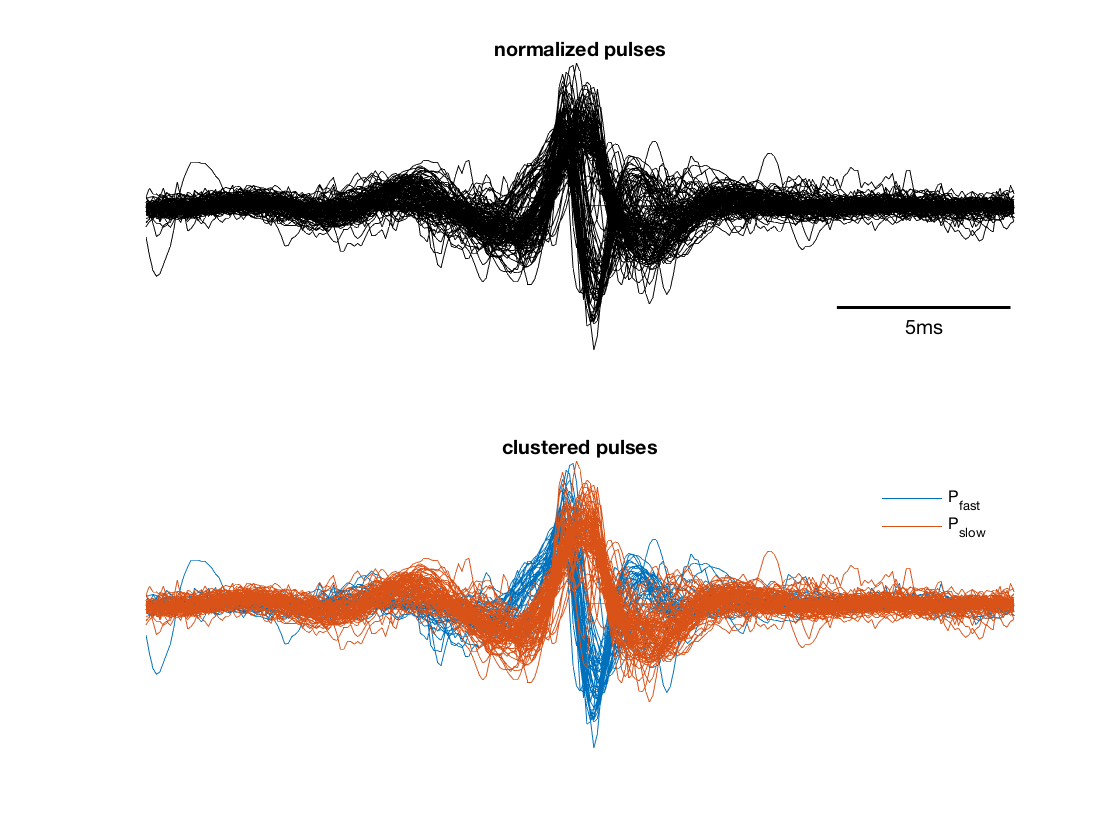

cols = lines(2);
subIdx = 1:20:size(pulseShapes,1);

subplot(211)
plot(pulseShapesNorm(subIdx,:)', 'k')
title('normalized pulses')
scalebar(200, -0.3, 50, '5ms',10)

subplot(212)
hp{1} = plot(pulseShapesNorm(subIdx(Gw(subIdx)==1),:)', 'Color', cols(1,:));
hold on
hp{2} = plot(pulseShapesNorm(subIdx(Gw(subIdx)==2),:)', 'Color', cols(2,:));
title('clustered pulses')
legend([hp{1}(1), hp{2}(1)], {'P_{fast}','P_{slow}'})
legend('boxoff')

axis(gcas, 'tight', 'off')

## Template-based pulse type classifier

An efficient pulse type classifier can be obtained by finding a boundary between pulse types based on their projection values onto the Pfast and Pslow centroid. In the paper, we used a quadratic boundary (see [https://github.com/murthylab/pulseTypeClassifier](https://github.com/murthylab/pulseTypeClassifier) for details) .

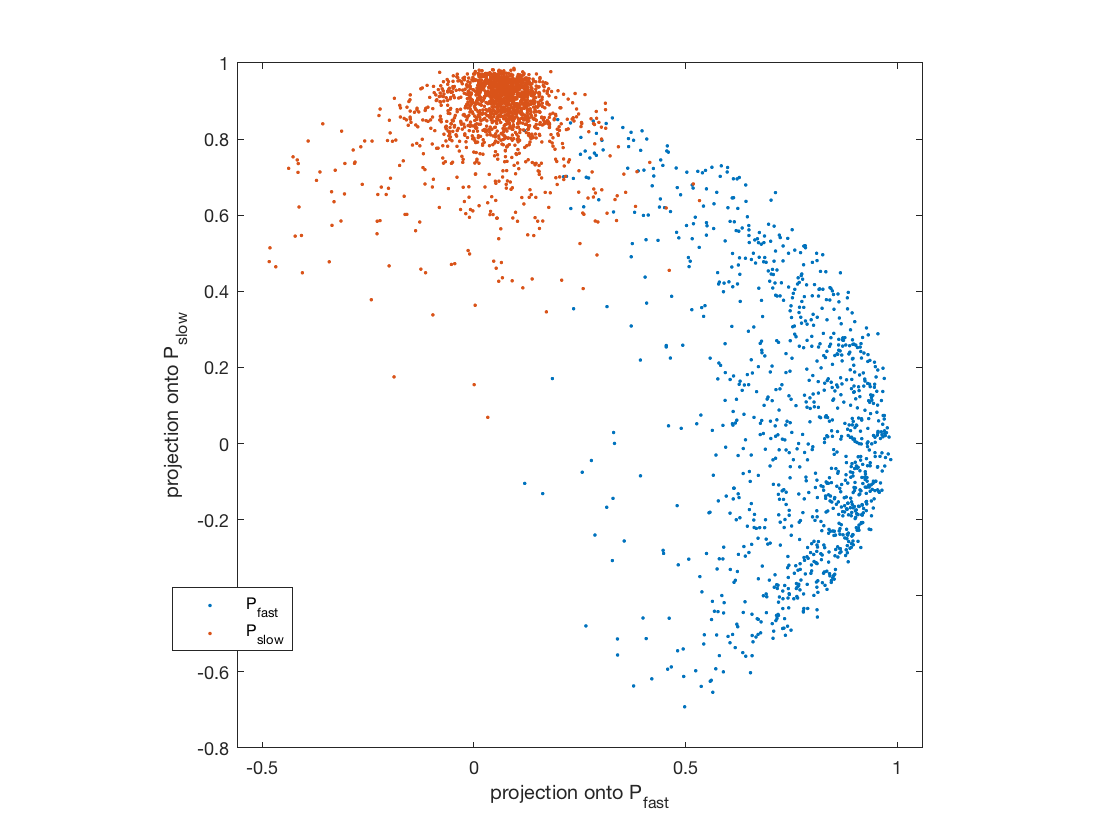

templates = normalize(grpstats(pulseShapesNorm, Gw));
projectedPulses = pulseShapesNorm*templates';
clf
gscatter(projectedPulses(:,1), projectedPulses(:,2), Gw, cmap(1:2,:))
xlabel('projection onto P_{fast}')
ylabel('projection onto P_{slow}')
legend({'P_{fast}', 'P_{slow}'})
axis('square')

## Analysis of pulse shapes

Analysis of pulse shapes in terms of pulse carrier frequency and pulse asymmetry confirms the separation into a slow, symmetrical and a fast, asymmetrical type.

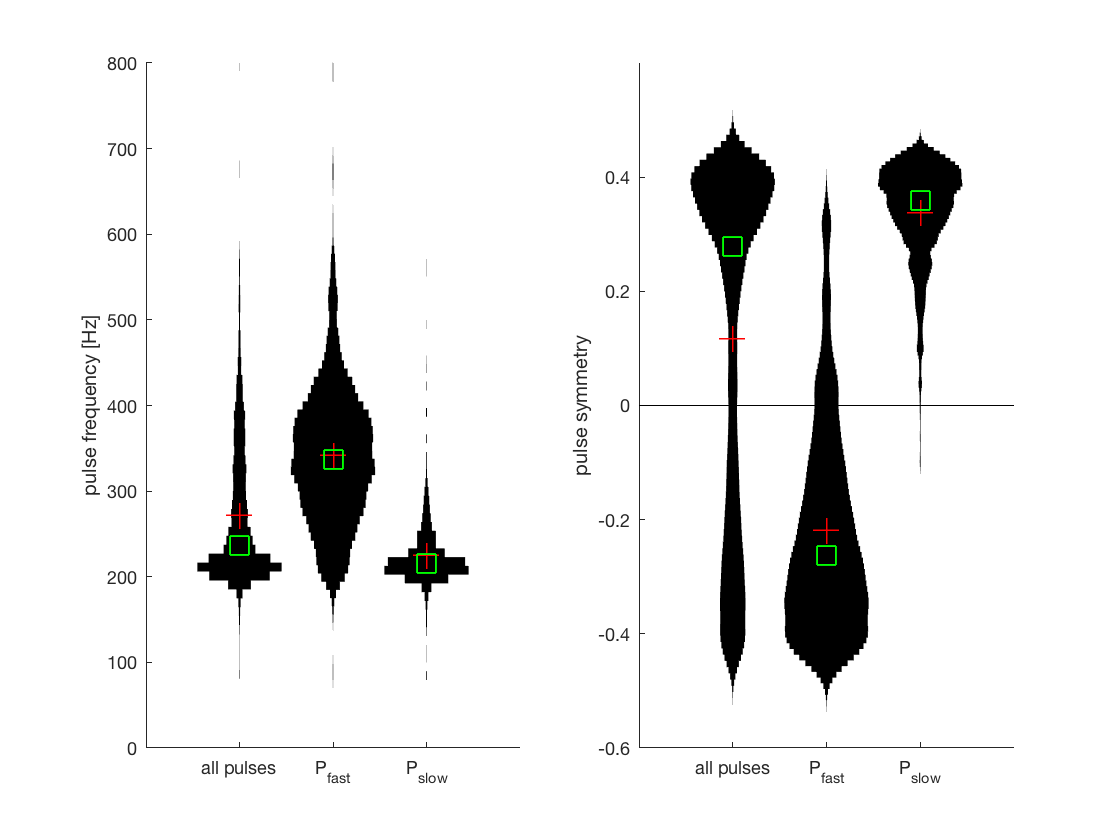

pulseFrequency = getPulseFreq(pulseShapesNorm');
pulseSymmetry = sum(pulseShapesNorm(:,1:125).*pulseShapesNorm(:,end:-1:127),2)';% LR symmetry

clf
subplot(121)
distributionPlot(pulseFrequency, 'xValues', 1)
distributionPlot(pulseFrequency, 'groups',Gw, 'xValues', [2 3])
set(gca, 'XTick', 1:3, 'XTickLabel', {'all pulses', 'P_{fast}' 'P_{slow}'}, 'YLim', [0 800])
ylabel('pulse frequency [Hz]')

subplot(122)
distributionPlot(pulseSymmetry', 'xValues', 1)
distributionPlot(pulseSymmetry', 'groups',Gw, 'xValues', [2 3])
set(gca, 'XTick', 1:3, 'XTickLabel', {'all pulses' 'P_{fast}' 'P_{slow}'}, 'YLim', [-0.6 0.6])
ylabel('pulse symmetry')
hline(0)